
% Limpieza del entorno
clear; clc; close all;

% CONFIGURACIÓN DEL BATCH
VIDEO_SET = [200, 400, 600, 800, 1000];
LOG_DIR = 'logs';

% COLORES INDIVIDUALES
c_blue   = [0.1216, 0.4667, 0.7059]; % Train Loss
c_orange = [1.0000, 0.4980, 0.0549]; % Val Loss
c_green  = [0.1725, 0.6275, 0.1725]; % Val AUC
c_purple = [0.5804, 0.4039, 0.7412]; % Val Acc
c_grid   = [0.85, 0.85, 0.85];       % Gris para la rejilla

% ALMACÉN DE DATOS
comparison_data = struct();
final_table_rows = [];

%% 0. PREPARACIÓN DE CARPETA (Mover fuera del bucle es más eficiente)
outputFolder = 'Resultados';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

## A. BUCLE PRINCIPAL (ANÁLISIS INDIVIDUAL)

%% A. BUCLE PRINCIPAL (ANÁLISIS INDIVIDUAL)
for i = 1:length(VIDEO_SET)
    num_videos = VIDEO_SET(i);

    % Construir rutas
    csv_train_path = fullfile(LOG_DIR, sprintf('training_metrics_%d.csv', num_videos));
    csv_test_path = fullfile(LOG_DIR, sprintf('test_results_%d.csv', num_videos));

    % VERIFICACIÓN
    if ~exist(csv_train_path, 'file')
        warning('Datos no encontrados para %d vídeos. Saltando...', num_videos);
        continue;
    end

    fprintf('\n>>> Analizando Experimento: %d Vídeos\n', num_videos);

    % CARGAR DATOS DE ENTRENAMIENTO
    opts = detectImportOptions(csv_train_path);
    T = readtable(csv_train_path, opts);

    % Estadísticas
    stats = groupsummary(T, 'Epoch', {'mean', 'std'},{'Train_Loss', 'Val_Loss', 'Val_Acc', 'Val_AUC'});
    epochs = stats.Epoch;

    % GUARDAR DATOS PARA LUEGO (COMPARATIVA)
    comparison_data(i).num_videos = num_videos;
    comparison_data(i).epochs = epochs;
    comparison_data(i).val_loss_mean = stats.mean_Val_Loss;
    comparison_data(i).val_loss_std = stats.std_Val_Loss;
    comparison_data(i).val_auc_mean = stats.mean_Val_AUC;
    comparison_data(i).val_auc_std = stats.std_Val_AUC;
    comparison_data(i).val_acc_mean = stats.mean_Val_Acc;
    comparison_data(i).val_acc_std = stats.std_Val_Acc;

### 1. GRÁFICA DE LOSS (INDIVIDUAL)

    %% 1. GRÁFICA DE LOSS (INDIVIDUAL)
    figure;
    figLoss = figure('Color', 'w', 'Position', [100, 100, 900, 550]);
    ax = gca; hold on;
    ax.FontSize = 14;

    plot_shaded(epochs, stats.mean_Train_Loss, stats.std_Train_Loss, c_blue, '-', 'Train Loss');
    plot_shaded(epochs, stats.mean_Val_Loss, stats.std_Val_Loss, c_orange, '--', 'Validation Loss');

    % title("Evolución de la Función de Pérdida - " + num_videos + " vídeos", 'FontSize', 13);
    xlabel('Época', 'FontSize', 14); 
    ylabel('Loss', 'FontSize', 14);

    xlim([0, 26]); 
    ylim([0, 1.1]);
    set(ax, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
    legend('Location', 'northeast', 'FontSize', 13, 'Box', 'on', 'EdgeColor', [0.8 0.8 0.8]);

    % --- GUARDADO DE GRÁFICA LOSS ---
    fileNameLoss = "loss_evolution_" + num_videos + ".png";
    fullPathLoss = fullfile(outputFolder, fileNameLoss);
    exportgraphics(figLoss, fullPathLoss, 'Resolution', 600);

### 2. GRÁFICA DE MÉTRICAS (INDIVIDUAL)

    %% 2. GRÁFICA DE MÉTRICAS (INDIVIDUAL)
    figMetrics = figure('Color', 'w', 'Position', [150, 150, 900, 550]);
    ax2 = gca; hold on;
    ax2.FontSize = 14;

    plot_shaded(epochs, stats.mean_Val_AUC, stats.std_Val_AUC, c_green, '-', 'Validation AUC');
    plot_shaded(epochs, stats.mean_Val_Acc, stats.std_Val_Acc, c_purple, '--', 'Validation Accuracy');

    % title("Evolución de Métricas de Validación - " + num_videos + " vídeos", 'FontSize', 13);
    xlabel('Época', 'FontSize', 14); 
    ylabel('Accuracy / AUC', 'FontSize', 14);

    xlim([0, 26]); ylim([0, 1.05]);
    set(ax2, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
    legend('Location', 'southeast', 'FontSize', 13, 'EdgeColor', [0.8 0.8 0.8]);

    % --- GUARDADO DE GRÁFICA MÉTRICAS ---
    fileNameMetrics = "metrics_evolution_" + num_videos + ".png";
    fullPathMetrics = fullfile(outputFolder, fileNameMetrics);
    exportgraphics(figMetrics, fullPathMetrics, 'Resolution', 600);

### 3. TABLA INDIVIDUAL DETALLADA

    %% 3. TABLA INDIVIDUAL DETALLADA
    if exist(csv_test_path, 'file')
        T_test = readtable(csv_test_path);

        fprintf('\n========================================\n');
        fprintf('TABLA DETALLADA (%d VÍDEOS)\n', num_videos);
        fprintf('========================================\n');
        disp(T_test);
        fprintf('----------------------------------------\n');

        avg_acc = mean(T_test.Test_Acc); std_acc = std(T_test.Test_Acc);
        avg_auc = mean(T_test.Test_AUC); std_auc = std(T_test.Test_AUC);

        fprintf('Accuracy Promedio: %.4f ± %.4f\n', avg_acc, std_acc);
        fprintf('AUC Promedio:      %.4f ± %.4f\n', avg_auc, std_auc);
        fprintf('========================================\n\n');

        % Guardar resumen
        new_row = table(num_videos, avg_acc, std_acc, avg_auc, std_auc,'VariableNames', {'Videos', 'Acc_Mean', 'Acc_Std', 'AUC_Mean', 'AUC_Std'});
        final_table_rows = [final_table_rows; new_row];
    else
        fprintf('No se encontró archivo de test: %s\n', csv_test_path);
    end
    
    % Cierra las figuras individuales para no saturar la RAM
    close(figLoss); close(figMetrics);
end


>>> Analizando Experimento: 200 Vídeos


TABLA DETALLADA (200 VÍDEOS)


    Run    Test_Acc    Test_AUC
    ___    ________    ________

     1         0.8     0.90045 
     2     0.76667       0.825 
     3     0.76667     0.86124 
     4         0.7     0.76786 
     5     0.83333     0.88393 



----------------------------------------


Accuracy Promedio: 0.7733 ± 0.0494


AUC Promedio:      0.8477 ± 0.0528



>>> Analizando Experimento: 400 Vídeos


TABLA DETALLADA (400 VÍDEOS)


    Run    Test_Acc    Test_AUC
    ___    ________    ________

     1     0.86667     0.98204 
     2     0.86667     0.94667 
     3     0.91667     0.98529 
     4     0.91667     0.97257 
     5        0.95     0.98032 



----------------------------------------


Accuracy Promedio: 0.9033 ± 0.0361


AUC Promedio:      0.9734 ± 0.0156



>>> Analizando Experimento: 600 Vídeos


TABLA DETALLADA (600 VÍDEOS)


    Run    Test_Acc    Test_AUC
    ___    ________    ________

     1     0.93333        0.99 
     2     0.81111       0.987 
     3         0.9     0.94321 
     4     0.88889     0.99061 
     5     0.97778     0.98565 



----------------------------------------


Accuracy Promedio: 0.9022 ± 0.0616


AUC Promedio:      0.9793 ± 0.0203



>>> Analizando Experimento: 800 Vídeos


TABLA DETALLADA (800 VÍDEOS)


    Run    Test_Acc    Test_AUC
    ___    ________    ________

     1     0.96667     0.99608 
     2        0.95      0.9947 
     3     0.94167     0.99067 
     4     0.95833     0.99634 
     5       0.975     0.98023 



----------------------------------------


Accuracy Promedio: 0.9583 ± 0.0132


AUC Promedio:      0.9916 ± 0.0068



>>> Analizando Experimento: 1000 Vídeos


TABLA DETALLADA (1000 VÍDEOS)


    Run    Test_Acc    Test_AUC
    ___    ________    ________

     1     0.95333     0.96959 
     2     0.94667     0.98645 
     3     0.84667       0.939 
     4     0.96667      0.9815 
     5     0.93333     0.98745 



----------------------------------------


Accuracy Promedio: 0.9293 ± 0.0477


AUC Promedio:      0.9728 ± 0.0202


## B. GENERACIÓN DE COMPARATIVAS (TODO JUNTO)

%% B. GENERACIÓN DE COMPARATIVAS (TODO JUNTO)
fprintf('\n\n');
fprintf('########################################\n');

########################################


fprintf('     COMPARATIVA FINAL DE ESTUDIO     \n');

     COMPARATIVA FINAL DE ESTUDIO     


fprintf('########################################\n');

########################################


### 1. TABLA UNIFICADA

% 1. TABLA UNIFICADA
if ~isempty(final_table_rows)
    disp('TABLA RESUMEN GLOBAL:');
    disp(final_table_rows);
end

TABLA RESUMEN GLOBAL:


    Videos    Acc_Mean    Acc_Std     AUC_Mean     AUC_Std 
    ______    ________    ________    ________    _________

      200     0.77333     0.049441     0.8477      0.052842
      400     0.90333     0.036132    0.97338      0.015648
      600     0.90222     0.061564    0.97929      0.020277
      800     0.95833     0.013176     0.9916     0.0067519
     1000     0.92933     0.047749     0.9728       0.02018



### 2. GRÁFICA COMPARATIVA: VALIDATION LOSS

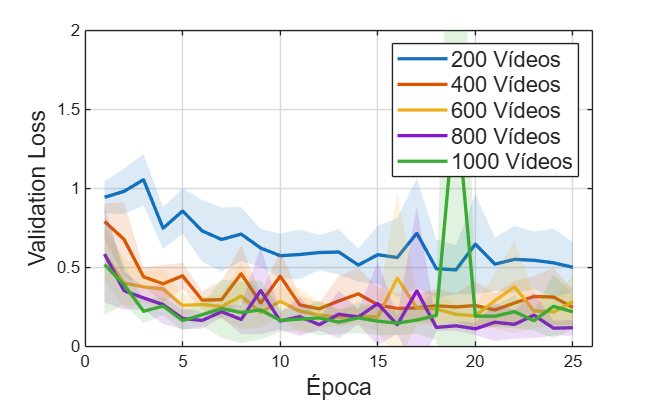

% 2. GRÁFICA COMPARATIVA: VALIDATION LOSS
% CORRECCIÓN: Asignamos handle a figCompLoss
figCompLoss = figure('Name', 'Comparativa Loss', 'Color', 'w', 'Position', [200, 200, 900, 550]);
ax_cl = gca; hold on;
default_colors = get(ax_cl, 'ColorOrder');

for i = 1:length(comparison_data)
    % Verificamos que el índice exista y tenga datos (por si hubo saltos)
    if i > length(comparison_data) || isempty(comparison_data(i).num_videos), continue; end
    
    color_idx = mod(i-1, size(default_colors, 1)) + 1;
    c = default_colors(color_idx, :);

    label_txt = sprintf('%d Vídeos', comparison_data(i).num_videos);

    plot_shaded(comparison_data(i).epochs, comparison_data(i).val_loss_mean, comparison_data(i).val_loss_std, c, '-', label_txt);
end

% title('Comparativa: Pérdida en Validación (Estabilidad)', 'FontSize', 13);
xlabel('Época', 'FontSize', 14); 
ylabel('Validation Loss', 'FontSize', 14);
xlim([0, 26]); 
%ylim([0, 4.5]);
ylim([0, 2]);

% CORRECCIÓN: 'GridColor' usa c_grid, no gridColor
set(ax_cl, 'Box', 'on', 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
legend('Location', 'northeast', 'FontSize', 13);

% --- GUARDADO COMPARATIVA LOSS (FALTABA ESTO) ---
fileCompLoss = fullfile(outputFolder, 'comparativa_validation_loss.png');
drawnow; exportgraphics(figCompLoss, fileCompLoss, 'Resolution', 600);

### 3. GRÁFICA COMPARATIVA: VALIDATION AUC

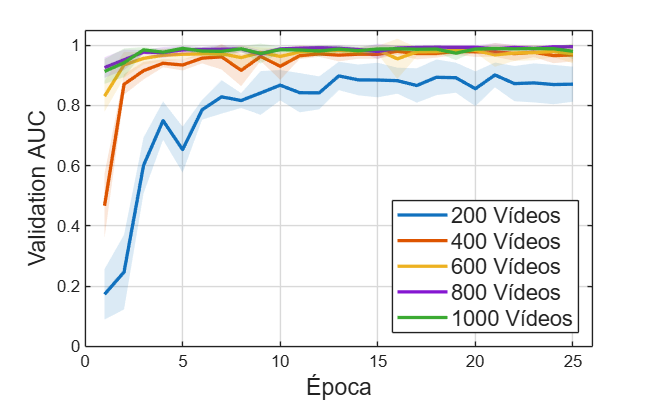

%% 3. GRÁFICA COMPARATIVA: VALIDATION AUC
figCompAUC = figure('Name', 'Comparativa AUC', 'Color', 'w', 'Position', [250, 250, 900, 550]);
ax_ca = gca; hold on;
default_colors = get(ax_ca, 'ColorOrder');

for i = 1:length(comparison_data)
     if i > length(comparison_data) || isempty(comparison_data(i).num_videos), continue; end

    color_idx = mod(i-1, size(default_colors, 1)) + 1;
    c = default_colors(color_idx, :);

    label_txt = sprintf('%d Vídeos', comparison_data(i).num_videos);

    plot_shaded(comparison_data(i).epochs,comparison_data(i).val_auc_mean,comparison_data(i).val_auc_std, c, '-', label_txt);
end

% title('Comparativa: AUC en Validación (Rendimiento)', 'FontSize', 13);
xlabel('Época', 'FontSize', 14); 
ylabel('Validation AUC', 'FontSize', 14);
xlim([0, 26]); ylim([0, 1.05]);

% CORRECCIÓN: 'GridColor' usa c_grid
set(ax_ca, 'Box', 'on', 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
legend('Location', 'southeast', 'FontSize', 13);

% --- GUARDADO COMPARATIVA AUC ---
fileCompAUC = fullfile(outputFolder, 'comparativa_validation_auc.png');
drawnow; exportgraphics(figCompAUC, fileCompAUC, 'Resolution', 600);

### FUNCIÓN AUXILIAR

%% FUNCIÓN AUXILIAR
function plot_shaded(x, y_mean, y_std, color, line_style, label_name)
    % 1. Forzar vectores columna para evitar error de dimensiones en [x; flip(x)]
    x = x(:);
    y_mean = y_mean(:);
    y_std = y_std(:);
    
    % 2. SANITIZACIÓN DE DATOS: Reemplazar NaNs con 0 en la desviación
    % Esto evita que 'fill' cuelgue el renderizador gráfico
    y_std(isnan(y_std)) = 0;
    
    % 3. Verificar que las longitudes coincidan
    if length(x) ~= length(y_mean)
        warning('Dimensiones incorrectas en plot_shaded para %s. Saltando fill.', label_name);
        plot(x, y_mean, 'Color', color, 'LineStyle', line_style, 'LineWidth', 2, 'DisplayName', label_name);
        return;
    end

    curve1 = y_mean + y_std;
    curve2 = y_mean - y_std;
    
    x2 = [x; flipud(x)];          % Usar flipud explícito para columnas
    inBetween = [curve1; flipud(curve2)];
    
    % 4. Dibujar sombra
    % 'EdgeColor', 'none' es crucial para rendimiento
    fill(x2, inBetween, color, 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
    
    % 5. Dibujar línea media
    plot(x, y_mean, 'Color', color, 'LineStyle', line_style, 'LineWidth', 2, 'DisplayName', label_name);
end


### 4. NUEVA GRÁFICA COMPARATIVA: VALIDATION ACCURACY

%% 4. NUEVA GRÁFICA COMPARATIVA: VALIDATION ACCURACY
fprintf('\n>>> Generando gráfica de Accuracy...\n');


>>> Generando gráfica de Accuracy...



figCompAcc = figure('Name', 'Comparativa Accuracy', 'Color', 'w', 'Position', [300, 300, 900, 550]);
ax_cacc = gca; hold on;

% Reiniciamos ciclo de colores para que coincida con las otras gráficas
set(gca, 'ColorOrderIndex', 1); 
default_colors = get(gca, 'ColorOrder');

for i = 1:length(comparison_data)
     % Chequeo de seguridad
     if i > length(comparison_data) || isempty(comparison_data(i).num_videos), continue; end

    % Asignación de color
    color_idx = mod(i-1, size(default_colors, 1)) + 1;
    c = default_colors(color_idx, :);
    
    label_txt = sprintf('%d Vídeos', comparison_data(i).num_videos);

    % DIBUJO (Usando los datos de Accuracy)
    plot_shaded(comparison_data(i).epochs, comparison_data(i).val_acc_mean, comparison_data(i).val_acc_std, c, '-', label_txt);
end

% Formato idéntico a las anteriores
xlabel('Época', 'FontSize', 14); 
ylabel('Validation Accuracy', 'FontSize', 14);
xlim([0, 26]); 
ylim([0, 1.05]); 

% Rejilla
if ~exist('c_grid', 'var'), c_grid = [0.85, 0.85, 0.85]; end
set(ax_cacc, 'Box', 'on', 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
legend('Location', 'southeast', 'FontSize', 13);

% --- GUARDADO CON EXPORTGRAPHICS ---
if ~exist('outputFolder', 'var'), outputFolder = 'Resultados'; end
fileCompAcc = fullfile(outputFolder, 'comparativa_validation_accuracy.png');

fprintf('Guardando imagen en: %s ...\n', fileCompAcc);

Guardando imagen en: Resultados\comparativa_validation_accuracy.png ...


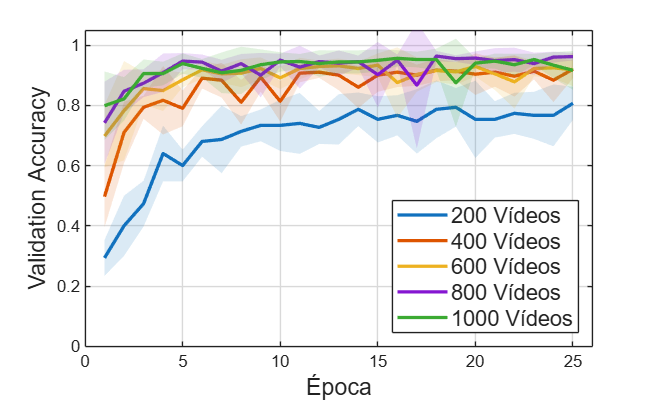


% IMPORTANTE: drawnow fuerza a terminar el dibujo antes de exportar para evitar cuelgues
drawnow; 
exportgraphics(figCompAcc, fileCompAcc, 'Resolution', 600);


fprintf('>>> ¡Gráfica de Accuracy exportada correctamente!\n');

>>> ¡Gráfica de Accuracy exportada correctamente!


## ANÁLISIS INDIVIDUAL: MODELO 2D BASE (EFFICIENTNET-B0)

%% ========================================================================
% ANÁLISIS INDIVIDUAL: MODELO 2D BASE (EFFICIENTNET-B0)
% ========================================================================
clc; clear; close all;

%% 0. PREPARACIÓN DE CARPETA
outputFolder = 'Resultados';
if ~exist(outputFolder, 'dir')
    mkdir(outputFolder);
end

% 1. Configuración de Rutas
LOG_DIR = 'logs';
csv_train_path = fullfile(LOG_DIR, 'training_metrics_2D.csv');
csv_test_path  = fullfile(LOG_DIR, 'test_results_2D.csv');

% Colores corporativos (mismos que el modelo 3D)
c_blue   = [0.1216, 0.4667, 0.7059]; % Train Loss
c_orange = [1.0000, 0.4980, 0.0549]; % Val Loss
c_green  = [0.1725, 0.6275, 0.1725]; % Val AUC
c_purple = [0.5804, 0.4039, 0.7412]; % Val Acc
c_grid   = [0.85, 0.85, 0.85];       % Gris rejilla

fprintf('>>> Analizando Resultados del Modelo 2D Base...\n');

>>> Analizando Resultados del Modelo 2D Base...



% 2. Verificación de archivos
if ~exist(csv_train_path, 'file')
    error('No se encuentra el archivo de entrenamiento 2D: %s', csv_train_path);
end

% 3. Carga y Agrupación Estadística (Media y STD por Época)
opts = detectImportOptions(csv_train_path);
T = readtable(csv_train_path, opts);

stats = groupsummary(T, 'Epoch', {'mean', 'std'}, ...
    {'Train_Loss', 'Val_Loss', 'Val_Acc', 'Val_AUC'});
epochs = stats.Epoch;

%% GRÁFICA 1: EVOLUCIÓN DE LA PÉRDIDA (LOSS) 2D
figLoss2D = figure('Name', 'Loss 2D', 'Color', 'w', 'Position', [100, 100, 900, 550]);
ax1 = gca; hold on;
ax1.FontSize = 14;

plot_shaded(epochs, stats.mean_Train_Loss, stats.std_Train_Loss, c_blue, '-', 'Train Loss (2D)');
plot_shaded(epochs, stats.mean_Val_Loss, stats.std_Val_Loss, c_orange, '--', 'Validation Loss (2D)');

xlabel('Época', 'FontSize', 14); 
ylabel('Loss', 'FontSize', 14);
xlim([0, 26]); 

set(ax1, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
legend('Location', 'northeast', 'FontSize', 13, 'Box', 'on', 'EdgeColor', [0.8 0.8 0.8]);

% --- GUARDADO ---
fileCompLoss = fullfile(outputFolder, 'comparativa_loss_2D.png');
fprintf('Guardando imagen en: %s ...\n', fileCompLoss);

Guardando imagen en: Resultados\comparativa_loss_2D.png ...


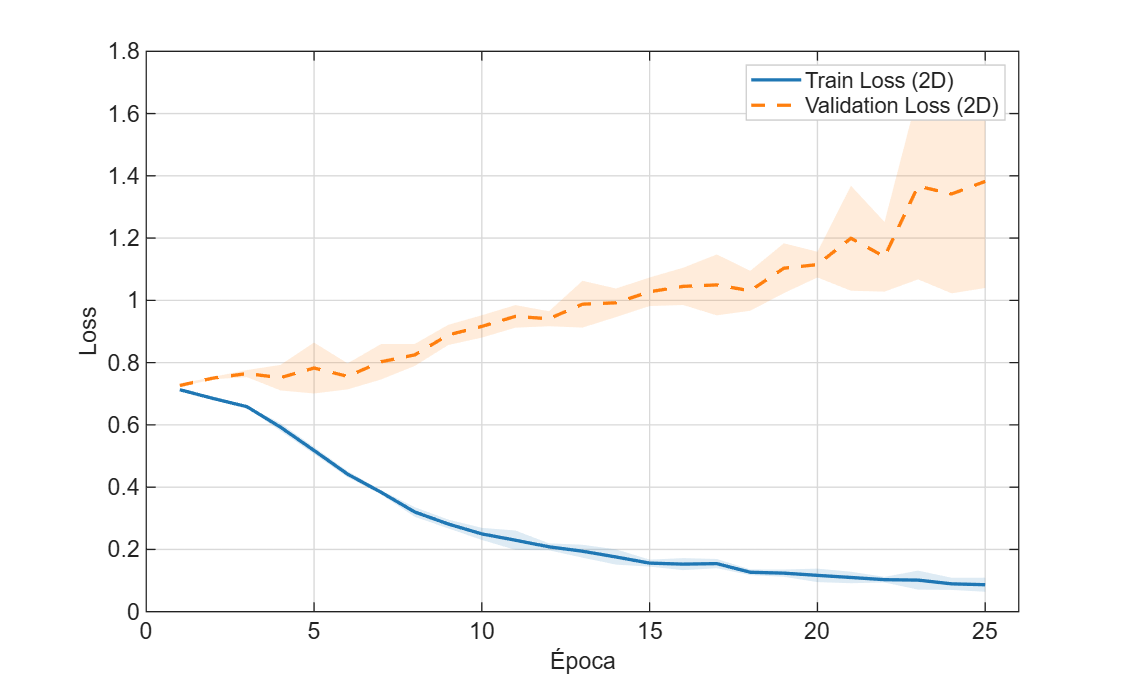

drawnow; 
exportgraphics(figLoss2D, fileCompLoss, 'Resolution', 600);


%% GRÁFICA 2: EVOLUCIÓN DE MÉTRICAS (ACCURACY Y AUC) 2D
figMetrics2D = figure('Name', 'Metrics 2D', 'Color', 'w', 'Position', [150, 150, 900, 550]);
ax2 = gca; hold on;
ax2.FontSize = 14;

plot_shaded(epochs, stats.mean_Val_AUC, stats.std_Val_AUC, c_green, '-', 'Validation AUC (2D)');
plot_shaded(epochs, stats.mean_Val_Acc, stats.std_Val_Acc, c_purple, '--', 'Validation Accuracy (2D)');

xlabel('Época', 'FontSize', 14); 
ylabel('Score (0-1)', 'FontSize', 14);
xlim([0, 26]); ylim([0, 1.05]);

set(ax2, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
legend('Location', 'southeast', 'FontSize', 13, 'EdgeColor', [0.8 0.8 0.8]);

% --- GUARDADO ---
fileCompMetrics = fullfile(outputFolder, 'comparativa_metrics_2D.png');
fprintf('Guardando imagen en: %s ...\n', fileCompMetrics);

Guardando imagen en: Resultados\comparativa_metrics_2D.png ...


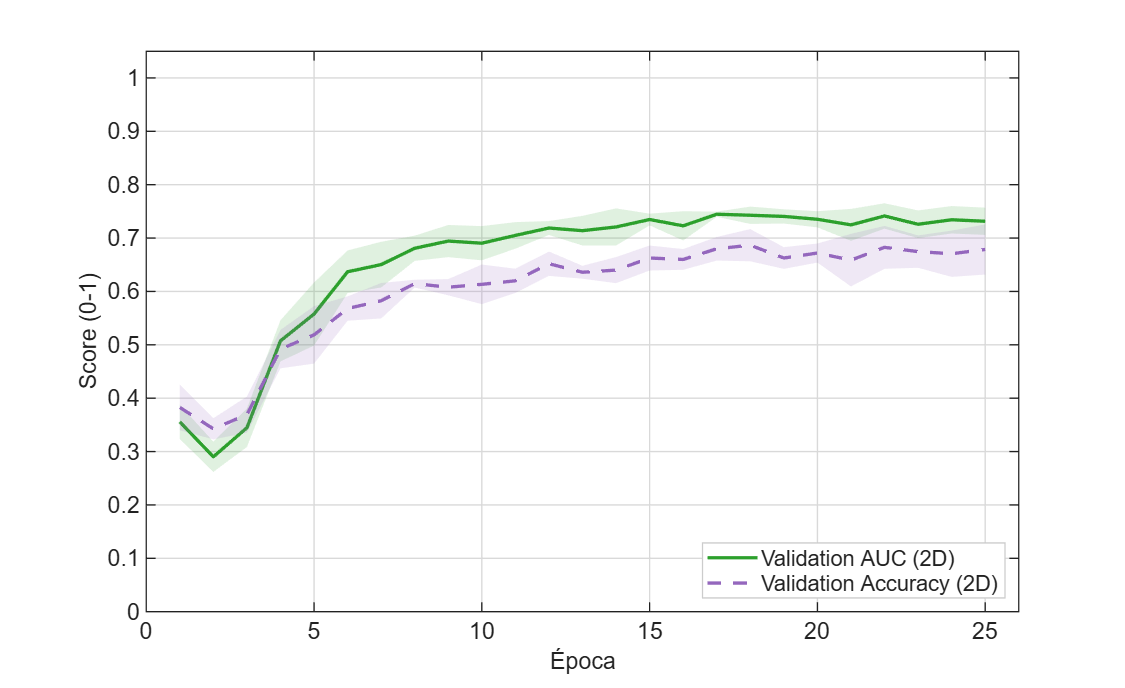

drawnow; 
exportgraphics(figMetrics2D, fileCompMetrics, 'Resolution', 600);


%% 4. RESULTADOS FINALES DE TEST 2D
if exist(csv_test_path, 'file')
    T_test = readtable(csv_test_path);
    avg_acc = mean(T_test.Test_Acc); std_acc = std(T_test.Test_Acc);
    avg_auc = mean(T_test.Test_AUC); std_auc = std(T_test.Test_AUC);

    fprintf('\n========================================\n');
    fprintf('   RESULTADOS FINALES TEST (MODELO 2D)  \n');
    fprintf('========================================\n');
    disp(T_test);
    fprintf('----------------------------------------\n');
    fprintf('Accuracy Promedio: %.4f ± %.4f\n', avg_acc, std_acc);
    fprintf('AUC Promedio:      %.4f ± %.4f\n', avg_auc, std_auc);
    fprintf('========================================\n\n');
else
    fprintf('\nNo se encontró el archivo de Test 2D aún.\n');
end

   RESULTADOS FINALES TEST (MODELO 2D)  


    Run    Test_Acc    Test_AUC
    ___    ________    ________

     1         0.7     0.75162 
     2     0.60667     0.68902 
     3     0.71333     0.76569 
     4     0.70667     0.78458 
     5         0.7     0.73471 



----------------------------------------


Accuracy Promedio: 0.6853 ± 0.0443


AUC Promedio:      0.7451 ± 0.0363



%% GRÁFICA COMPARATIVA FINAL: AUC 3D vs 2D (BARRAS CON DESVIACIÓN)
% 1. Datos de los modelos extraídos de las tablas finales
modelos = {'TD-3DCNN (800)', 'TD-3DCNN (1000)', 'EfficientNet 2D (1000)'};
auc_means = [0.9916, 0.9728, 0.7451];
auc_stds  = [0.0068, 0.0202, 0.0363];

% 2. Configuración de la figura
figBar = figure('Name', 'Comparativa Final AUC', 'Color', 'w', 'Position', [200, 200, 800, 500]);
ax = gca; hold on;

% 3. Colores corporativos (Morado para 800, Verde para 1000 3D, Azul para 2D)
c_3D_800  = [0.5804, 0.4039, 0.7412]; 
c_3D_1000 = [0.1725, 0.6275, 0.1725]; 
c_2D_1000 = [0.1216, 0.4667, 0.7059]; 

% 4. Dibujar barras
b = bar(1:3, auc_means, 'FaceColor', 'flat', 'EdgeColor', 'none', 'BarWidth', 0.6);
b.CData(1,:) = c_3D_800;
b.CData(2,:) = c_3D_1000;
b.CData(3,:) = c_2D_1000;

% 5. Dibujar barras de error (Desviación estándar)
errorbar(1:3, auc_means, auc_stds, 'k', 'LineStyle', 'none', 'LineWidth', 1.5, 'CapSize', 15);

% 6. Textos y Formato de Ejes
set(ax, 'XTick', 1:3, 'XTickLabel', modelos, 'FontSize', 13);
ylabel('AUC Promedio', 'FontSize', 14);
% title('Comparativa Directa de Rendimiento: Modelos 3D vs 2D', 'FontSize', 16);
ylim([0.65, 1.05]); % Límite ajustado para que la barra del 2D se vea bien respecto a las 3D

% 7. Añadir los números encima de cada barra
for i = 1:3
    text(i, auc_means(i) + auc_stds(i) + 0.015, sprintf('%.4f', auc_means(i)), ...
        'HorizontalAlignment', 'center', 'FontSize', 12, 'FontWeight', 'bold', 'Color', [0.2 0.2 0.2]);
end

% 8. Rejilla
grid on;
set(ax, 'GridColor', [0.8 0.8 0.8], 'GridAlpha', 0.8, 'Layer', 'bottom');

% --- GUARDADO ---
fileCompBar = fullfile(outputFolder, 'comparativa_barras_auc.png');
fprintf('Guardando imagen en: %s ...\n', fileCompBar);

Guardando imagen en: Resultados\comparativa_barras_auc.png ...


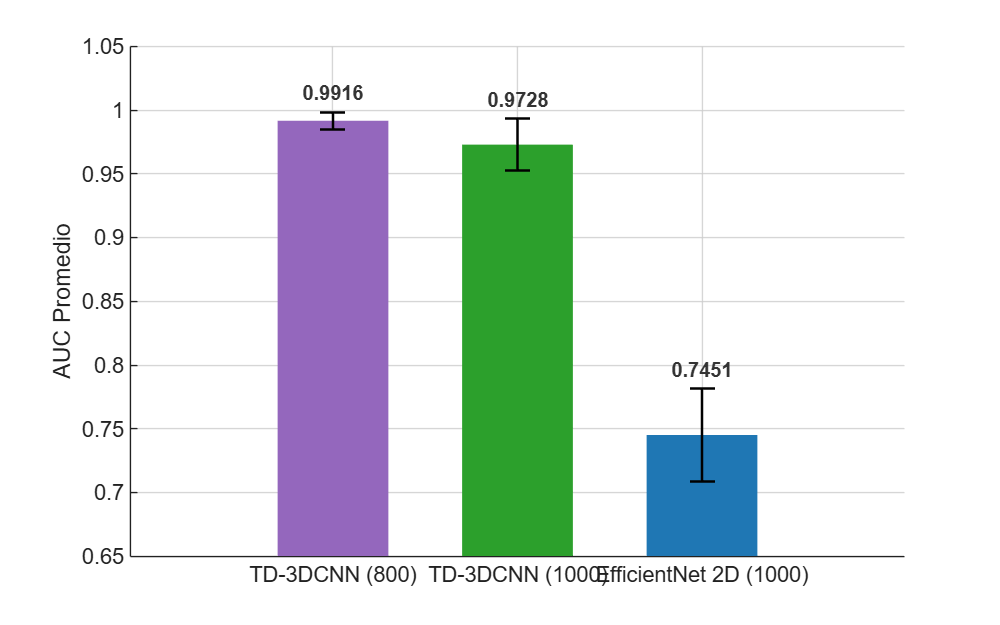

drawnow; 
exportgraphics(figBar, fileCompBar, 'Resolution', 600);

## EXPERIMENTO INTERMEDIO: ESTABILIZACIÓN MATEMÁTICA (SCHEDULER + L2)

%% ========================================================================
% EXPERIMENTO INTERMEDIO: ESTABILIZACIÓN MATEMÁTICA (SCHEDULER + L2)
% ========================================================================
fprintf('\n>>> Analizando Experimento Intermedio: Scheduler y L2 (batch_size=2, 25 épocas)\n');


>>> Analizando Experimento Intermedio: Scheduler y L2 (batch_size=2, 25 épocas)


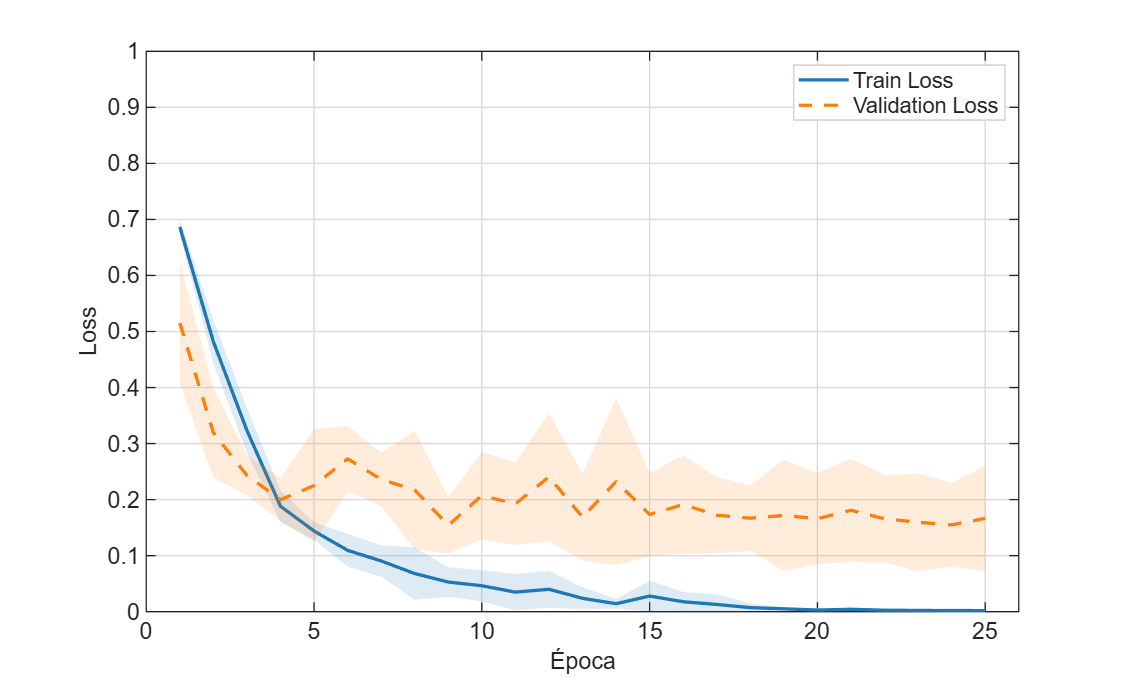

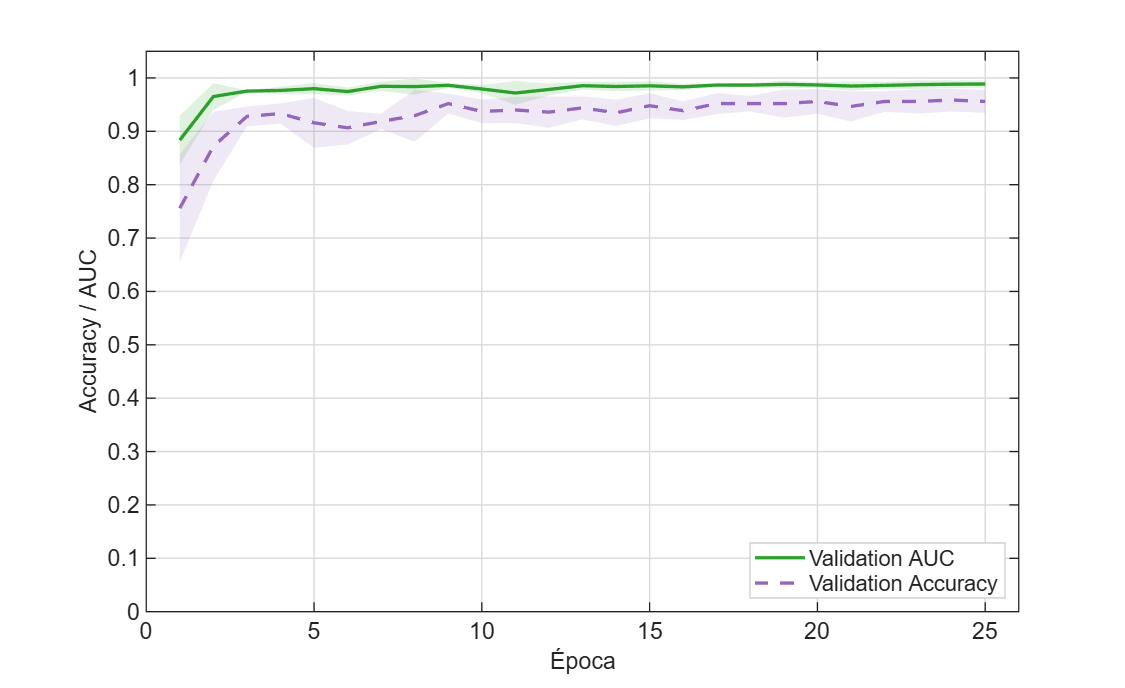

TABLA Experimento INTERMEDIO (N=1000)


    Run    Test_Acc    Test_AUC
    ___    ________    ________

     1     0.95333     0.99591 
     2     0.96667     0.99893 
     3     0.96667     0.99198 
     4        0.94     0.99377 
     5     0.97333     0.99552 



----------------------------------------


Accuracy Promedio: 0.9600 ± 0.0133


AUC Promedio:      0.9952 ± 0.0026



% Configuración de rutas compatibles con Windows
LOG_DIR_MEDIO = 'logs_paper';
NUM_VIDEOS_MEDIO = 1000; 

% CORRECCIÓN: Añadido el identificador "_medio_" a los nombres de archivo
csv_train_medio_path = fullfile(LOG_DIR_MEDIO, sprintf('training_metrics_medio_%d.csv', NUM_VIDEOS_MEDIO));
csv_test_medio_path  = fullfile(LOG_DIR_MEDIO, sprintf('test_results_medio_%d.csv', NUM_VIDEOS_MEDIO));

if exist(csv_train_medio_path, 'file')
    % 1. Cargar y agrupar los datos de los 5 Runs
    opts_medio = detectImportOptions(csv_train_medio_path);
    T_medio = readtable(csv_train_medio_path, opts_medio);
    
    stats_medio = groupsummary(T_medio, 'Epoch', {'mean', 'std'}, {'Train_Loss', 'Val_Loss', 'Val_Acc', 'Val_AUC'});
    epochs_medio = stats_medio.Epoch;

    % Comprobación de seguridad para paleta corporativa
    if ~exist('c_blue', 'var'), c_blue = [0.1216, 0.4667, 0.7059]; end
    if ~exist('c_orange', 'var'), c_orange = [1.0000, 0.4980, 0.0549]; end
    if ~exist('c_green', 'var'), c_green = [0.1725, 0.6275, 0.1725]; end
    if ~exist('c_purple', 'var'), c_purple = [0.5804, 0.4039, 0.7412]; end
    if ~exist('c_grid', 'var'), c_grid = [0.85, 0.85, 0.85]; end

    %% 1. GRÁFICA DE LOSS (EXPERIMENTO INTERMEDIO)
    figLossMedio = figure('Color', 'w', 'Position', [450, 200, 900, 550], 'Name', 'Intermedio - Evolución Loss');
    ax_lm = gca; hold on;
    ax_lm.FontSize = 14;

    plot_shaded(epochs_medio, stats_medio.mean_Train_Loss, stats_medio.std_Train_Loss, c_blue, '-', 'Train Loss');
    plot_shaded(epochs_medio, stats_medio.mean_Val_Loss, stats_medio.std_Val_Loss, c_orange, '--', 'Validation Loss');

    xlabel('Época', 'FontSize', 14); 
    ylabel('Loss', 'FontSize', 14);
    xlim([0, 26]);  ylim([0, 1]);  
    set(ax_lm, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
    legend('Location', 'northeast', 'FontSize', 13, 'Box', 'on', 'EdgeColor', [0.8 0.8 0.8]);

    % Guardado automático
    fileOutLossMedio = fullfile(outputFolder, 'medio_loss_evolution.png');
    drawnow; exportgraphics(figLossMedio, fileOutLossMedio, 'Resolution', 600);

    %% 2. GRÁFICA DE MÉTRICAS (ACCURACY Y AUC) (EXPERIMENTO INTERMEDIO)
    figMetricsMedio = figure('Color', 'w', 'Position', [500, 250, 900, 550], 'Name', 'Intermedio - Evolución Métricas');
    ax_mm = gca; hold on;
    ax_mm.FontSize = 14;

    plot_shaded(epochs_medio, stats_medio.mean_Val_AUC, stats_medio.std_Val_AUC, c_green, '-', 'Validation AUC');
    plot_shaded(epochs_medio, stats_medio.mean_Val_Acc, stats_medio.std_Val_Acc, c_purple, '--', 'Validation Accuracy');

    xlabel('Época', 'FontSize', 14); 
    ylabel('Accuracy / AUC', 'FontSize', 14);
    xlim([0, 26]); ylim([0, 1.05]);
    set(ax_mm, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
    legend('Location', 'southeast', 'FontSize', 13, 'EdgeColor', [0.8 0.8 0.8]);

    % Guardado automático
    fileOutMetricsMedio = fullfile(outputFolder, 'medio_metrics_evolution.png');
    drawnow; exportgraphics(figMetricsMedio, fileOutMetricsMedio, 'Resolution', 600);

    %% 3. TABLA DE RESULTADOS DE TEST (EXPERIMENTO INTERMEDIO)
    if exist(csv_test_medio_path, 'file')
        T_test_medio = readtable(csv_test_medio_path);
        
        fprintf('\n========================================\n');
        fprintf('TABLA Experimento INTERMEDIO (N=%d)\n', NUM_VIDEOS_MEDIO);
        fprintf('========================================\n');
        disp(T_test_medio);
        fprintf('----------------------------------------\n');
        
        avg_acc_m = mean(T_test_medio.Test_Acc); std_acc_m = std(T_test_medio.Test_Acc);
        avg_auc_m = mean(T_test_medio.Test_AUC); std_auc_m = std(T_test_medio.Test_AUC);
        
        fprintf('Accuracy Promedio: %.4f ± %.4f\n', avg_acc_m, std_acc_m);
        fprintf('AUC Promedio:      %.4f ± %.4f\n', avg_auc_m, std_auc_m);
        fprintf('========================================\n\n');
    else
        fprintf('No se encontró el archivo de rendimiento final de test: %s\n', csv_test_medio_path);
    end
else
    warning('No se han encontrado los archivos de registro en %s. Asegúrate de que el script de Python haya finalizado.', csv_train_medio_path);
end

## EXPERIMENTO PAPER: CONFIGURACIÓN 100% OPTIMIZADA

%% ========================================================================
% EXPERIMENTO PAPER: CONFIGURACIÓN 100% OPTIMIZADA
% ========================================================================
fprintf('\n>>> Analizando Experimento del Paper: N=1000 con Configuración Optimizada\n');


>>> Analizando Experimento del Paper: N=1000 con Configuración Optimizada


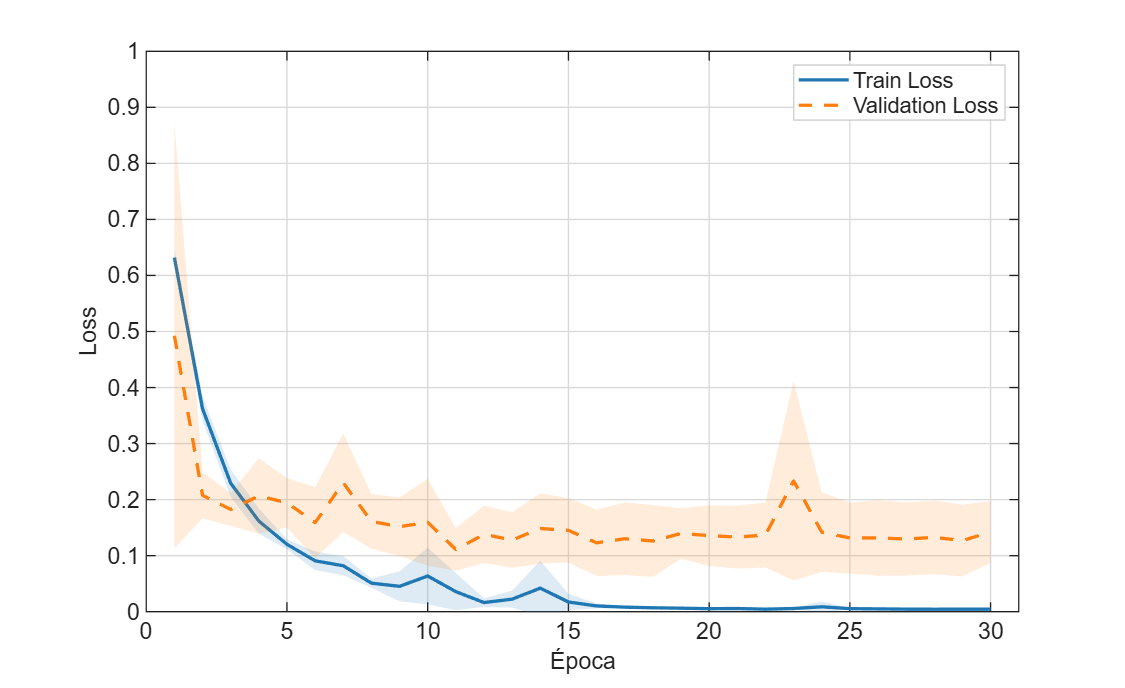

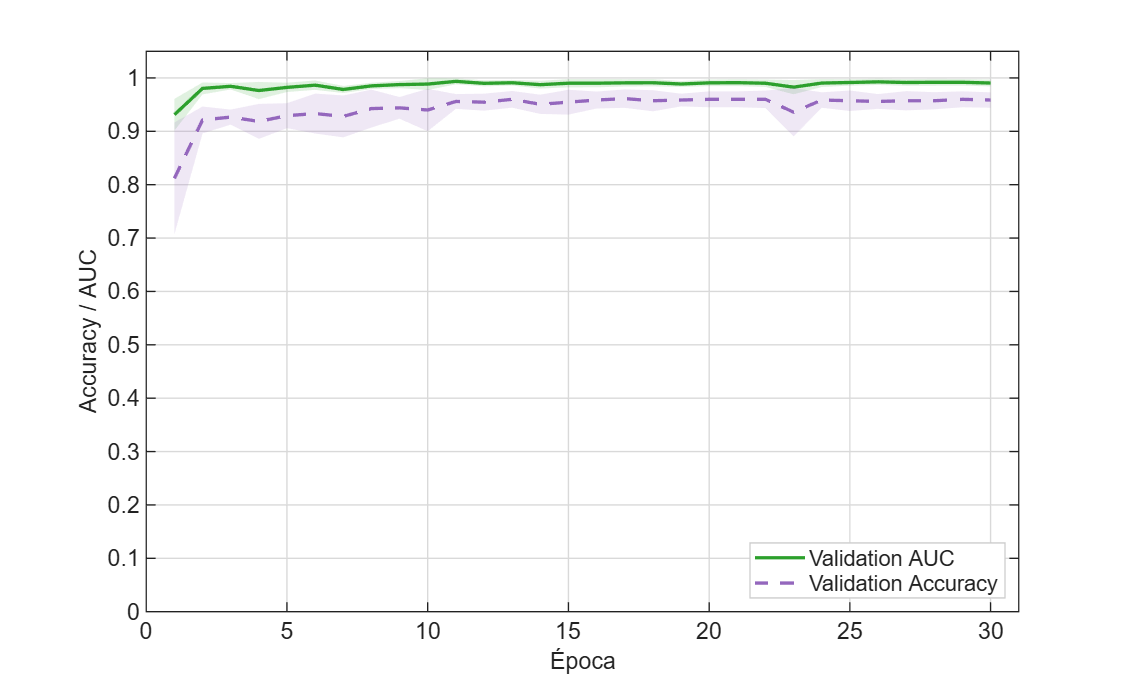

TABLA Experimento COMPLETO (N=1000)


    Run    Test_Acc    Test_AUC
    ___    ________    ________

     1     0.99333     0.99964 
     2     0.95333     0.99429 
     3        0.94     0.99395 
     4     0.95333     0.98915 
     5        0.96     0.98615 



----------------------------------------


Accuracy Promedio: 0.9600 ± 0.0200


AUC Promedio:      0.9926 ± 0.0052



% Definimos las rutas compatibles con tu sistema Windows 11
LOG_DIR_PAPER = 'logs_paper';
NUM_VIDEOS_PAPER = 1000; 

% CORRECCIÓN: Añadido el identificador "_completo_" a los nombres de archivo
csv_train_paper_path = fullfile(LOG_DIR_PAPER, sprintf('training_metrics_completo_%d.csv', NUM_VIDEOS_PAPER));
csv_test_paper_path  = fullfile(LOG_DIR_PAPER, sprintf('test_results_completo_%d.csv', NUM_VIDEOS_PAPER));

if exist(csv_train_paper_path, 'file')
    % 1. Cargar y agrupar los datos de los 5 Runs optimizados
    opts_paper = detectImportOptions(csv_train_paper_path);
    T_paper = readtable(csv_train_paper_path, opts_paper);
    
    stats_paper = groupsummary(T_paper, 'Epoch', {'mean', 'std'}, {'Train_Loss', 'Val_Loss', 'Val_Acc', 'Val_AUC'});
    epochs_paper = stats_paper.Epoch;

    % Aseguramos que los colores de tu paleta existan en memoria
    if ~exist('c_blue', 'var'), c_blue = [0.1216, 0.4667, 0.7059]; end
    if ~exist('c_orange', 'var'), c_orange = [1.0000, 0.4980, 0.0549]; end
    if ~exist('c_green', 'var'), c_green = [0.1725, 0.6275, 0.1725]; end
    if ~exist('c_purple', 'var'), c_purple = [0.5804, 0.4039, 0.7412]; end
    if ~exist('c_grid', 'var'), c_grid = [0.85, 0.85, 0.85]; end

    %% 1. GRÁFICA DE LOSS (EXPERIMENTO PAPER)
    figLossPaper = figure('Color', 'w', 'Position', [350, 100, 900, 550], 'Name', 'Paper - Evolución Loss');
    ax_lp = gca; hold on;
    ax_lp.FontSize = 14;

    plot_shaded(epochs_paper, stats_paper.mean_Train_Loss, stats_paper.std_Train_Loss, c_blue, '-', 'Train Loss');
    plot_shaded(epochs_paper, stats_paper.mean_Val_Loss, stats_paper.std_Val_Loss, c_orange, '--', 'Validation Loss');

    xlabel('Época', 'FontSize', 14); 
    ylabel('Loss', 'FontSize', 14);
    xlim([0, 31]);  ylim([0, 1]);
    set(ax_lp, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
    legend('Location', 'northeast', 'FontSize', 13, 'Box', 'on', 'EdgeColor', [0.8 0.8 0.8]);

    % Guardado automático
    fileOutLossPaper = fullfile(outputFolder, 'paper_loss_evolution_1000.png');
    drawnow; exportgraphics(figLossPaper, fileOutLossPaper, 'Resolution', 600);

    %% 2. GRÁFICA DE MÉTRICAS (ACCURACY Y AUC) (EXPERIMENTO PAPER)
    figMetricsPaper = figure('Color', 'w', 'Position', [400, 150, 900, 550], 'Name', 'Paper - Evolución Métricas');
    ax_mp = gca; hold on;
    ax_mp.FontSize = 14;

    plot_shaded(epochs_paper, stats_paper.mean_Val_AUC, stats_paper.std_Val_AUC, c_green, '-', 'Validation AUC');
    plot_shaded(epochs_paper, stats_paper.mean_Val_Acc, stats_paper.std_Val_Acc, c_purple, '--', 'Validation Accuracy');

    xlabel('Época', 'FontSize', 14); 
    ylabel('Accuracy / AUC', 'FontSize', 14);
    xlim([0, 31]); ylim([0, 1.05]);
    set(ax_mp, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;
    legend('Location', 'southeast', 'FontSize', 13, 'EdgeColor', [0.8 0.8 0.8]);

    % Guardado automático
    fileOutMetricsPaper = fullfile(outputFolder, 'paper_metrics_evolution_1000.png');
    drawnow; exportgraphics(figMetricsPaper, fileOutMetricsPaper, 'Resolution', 600);

    %% 3. TABLA DE RESULTADOS DE TEST (EXPERIMENTO PAPER)
    if exist(csv_test_paper_path, 'file')
        T_test_paper = readtable(csv_test_paper_path);
        
        fprintf('\n========================================\n');
        fprintf('TABLA Experimento COMPLETO (N=%d)\n', NUM_VIDEOS_PAPER);
        fprintf('========================================\n');
        disp(T_test_paper);
        fprintf('----------------------------------------\n');
        
        avg_acc_p = mean(T_test_paper.Test_Acc); std_acc_p = std(T_test_paper.Test_Acc);
        avg_auc_p = mean(T_test_paper.Test_AUC); std_auc_p = std(T_test_paper.Test_AUC);
        
        fprintf('Accuracy Promedio: %.4f ± %.4f\n', avg_acc_p, std_acc_p);
        fprintf('AUC Promedio:      %.4f ± %.4f\n', avg_auc_p, std_auc_p);
        fprintf('========================================\n\n');
    else
        fprintf('No se encontró el archivo de rendimiento final de test: %s\n', csv_test_paper_path);
    end
else
    warning('No se han encontrado los archivos de registro en %s. Asegúrate de que el script de Python haya finalizado.', csv_train_paper_path);
end

## ABLATION STUDY: GRÁFICA COMPARATIVA


%% ========================================================================
% ABLATION STUDY: GRÁFICA COMPARATIVA ÚNICA (VALIDATION LOSS N=1000)
% ========================================================================
fprintf('\n>>> Generando Gráfica Comparativa Única del Ablation Study...\n');


>>> Generando Gráfica Comparativa Única del Ablation Study...


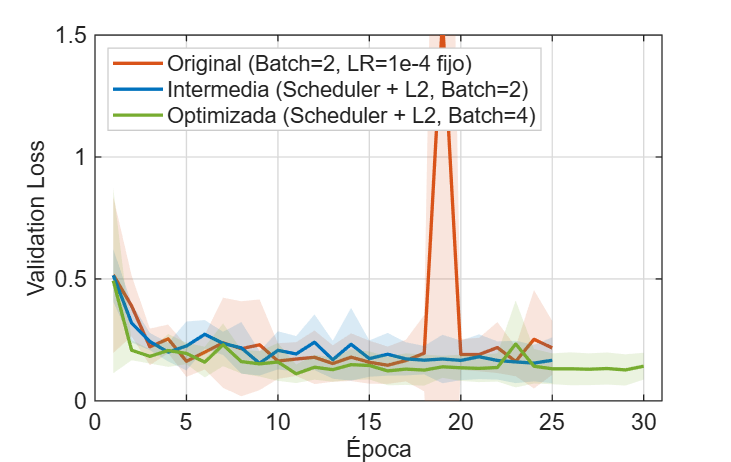

>>> ¡Gráfica del Ablation Study exportada correctamente en Resultados\ablation_comparativa_loss_1000.png!



% 1. Definir rutas exactas de los tres experimentos para N=1000
path_orig = fullfile('logs', 'training_metrics_1000.csv');
path_med  = fullfile('logs_paper', 'training_metrics_medio_1000.csv');
path_opt  = fullfile('logs_paper', 'training_metrics_completo_1000.csv');

% 2. Comprobar que existen los tres archivos antes de proceder
if exist(path_orig, 'file') && exist(path_med, 'file') && exist(path_opt, 'file')

    % 3. Cargar y extraer estadísticas de Validation Loss para cada uno
    T_orig = readtable(path_orig);
    stats_orig = groupsummary(T_orig, 'Epoch', {'mean', 'std'}, 'Val_Loss');

    T_med = readtable(path_med);
    stats_med = groupsummary(T_med, 'Epoch', {'mean', 'std'}, 'Val_Loss');

    T_opt = readtable(path_opt);
    stats_opt = groupsummary(T_opt, 'Epoch', {'mean', 'std'}, 'Val_Loss');

    % 4. Configurar la Figura
    figAblation = figure('Name', 'Ablation Study - Val Loss', 'Color', 'w', 'Position', [250, 250, 950, 600]);
    ax_abl = gca; hold on;
    ax_abl.FontSize = 14;

    % 5. Colores semánticos para diferenciar visualmente el progreso
    c_orig = [0.8500, 0.3250, 0.0980]; % Rojo/Naranja (Para la explosión del gradiente)
    c_med  = [0.0000, 0.4470, 0.7410]; % Azul oscuro (Para la estabilización intermedia)
    c_opt  = [0.4660, 0.6740, 0.1880]; % Verde (Para el éxito optimizado)

    % 6. Dibujar usando tu función plot_shaded
    plot_shaded(stats_orig.Epoch, stats_orig.mean_Val_Loss, stats_orig.std_Val_Loss, c_orig, '-', 'Original (Batch=2, LR=1e-4 fijo)');
    plot_shaded(stats_med.Epoch,  stats_med.mean_Val_Loss,  stats_med.std_Val_Loss,  c_med,  '-', 'Intermedia (Scheduler + L2, Batch=2)');
    plot_shaded(stats_opt.Epoch,  stats_opt.mean_Val_Loss,  stats_opt.std_Val_Loss,  c_opt,  '-', 'Optimizada (Scheduler + L2, Batch=4)');

    % 7. Formato y etiquetas
    xlabel('Época', 'FontSize', 14); 
    ylabel('Validation Loss', 'FontSize', 14);
    xlim([0, 31]); % Extendemos a 31 para que quepa el optimizado de 30 épocas

    % Ajuste del límite Y: si tu explosión de gradiente supera el 1.5, sube este número.
    ylim([0, 1.5]); 

    if ~exist('c_grid', 'var'), c_grid = [0.85, 0.85, 0.85]; end
    set(ax_abl, 'Box', 'on', 'LineWidth', 0.8, 'GridColor', c_grid, 'GridAlpha', 1, 'Layer', 'bottom'); grid on;

    % Colocar la leyenda arriba a la izquierda suele molestar menos a las curvas de Loss
    legend('Location', 'northwest', 'FontSize', 13, 'Box', 'on', 'EdgeColor', [0.8 0.8 0.8]);

    % 8. Guardar figura automáticamente
    if ~exist('outputFolder', 'var'), outputFolder = 'Resultados'; end
    fileAblation = fullfile(outputFolder, 'ablation_comparativa_loss_1000.png');
    drawnow; 
    exportgraphics(figAblation, fileAblation, 'Resolution', 600);

    fprintf('>>> ¡Gráfica del Ablation Study exportada correctamente en %s!\n', fileAblation);
else
    warning('Falta algún archivo CSV. Comprueba que las rutas de los 3 experimentos son correctas.');
end